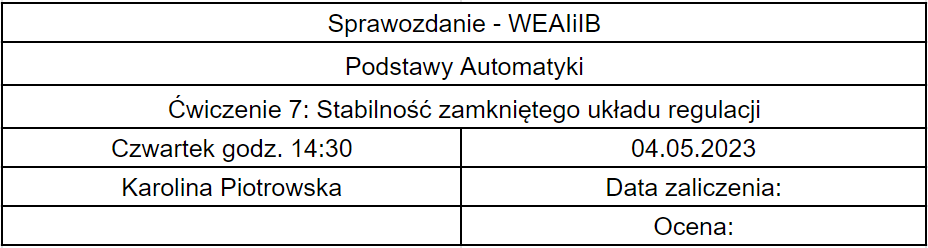

## Cel ćwiczenia

Ćwiczenie miało na celu zbadanie stabiolności zamkniętego układu przy pomocy kryterium Hurwitza i Nyquista.

## Wstęp teoretyczny

W ćwiczeniu wykorzystano zamknięty układ regulacji składający się z obiektu o transmitancji $G_{o}(s) = \frac{10}{s^3 + 2s^2 + 2s + 1}$ i regulatora PID o transmitancji $G_{r}(s) = k (1 + \frac{1}{T_{i}s} + \frac{T_{d}s}{Ts + 1})$.

Kryterium Hurwitza polega na sprawdzeniu, czy wszystkie minory główne macierzy skonstruowanej ze współczynników wielomianu znajdującego się z mianowniku transmitancji układu są większe od zera. Warunkiem koniecznym jest, aby współczynniki te były większe od zera. Jeżeli minory głównej tej macierzy są dodatnie, toukład jest stabilny.

Kryterium Nyquista polega na sprawdzeniu, czy w charakterystyce Nyquista wykres przechodzi przez punkt (-1, j0).

## Przebieg laboratorium

Do wykonania laboratorium użyto poniższych funkcji:

%function [] = print_step(k, Ti, Td, T)

licz_o = 10;
mian_o = [1 2 2 1];
licz_r = [k * (Ti * T + Td * Ti) k * (Ti + T) k];
mian_r = [Ti * T Ti 0];
[lo, mo] = series(licz_o, mian_o, licz_r, mian_r);
[lz, mz] = cloop(lo, mo, -1);
figure
step(lz, mz)
xlabel('Czas')
ylabel('Odpowiedź obiektu')
title('Odpowiedź skokowa')

%end

%function [] = nyquist_comp(k, Ti, Td, T)

licz_o = 10;
mian_o = [1 2 2 1];
licz_r = [k * (Ti * T + Td * Ti), k * (Ti + T), k];
mian_r = [Ti * T, Ti, 0];
[lo, mo] = series(licz_o, mian_o, licz_r, mian_r);
figure
nyquist(lo, mo)
axis([-10 0 -1 1])
xlabel('Re')
ylabel('Im')
title('Charakterystyka Nyquista')

%end

%function [] = hurwitz_comp(k, Ti, Td, T)

dog = imread('dog.jpg');
nope = imread('nope.jpg');
licz_o = 10;
mian_o = [1 2 2 1];
licz_r = [k * (Ti * T + Td * Ti) k * (Ti + T) k];
mian_r = [Ti * T Ti 0];
[lo, mo] = series(licz_o, mian_o, licz_r, mian_r);
[lz, mz] = cloop(lo, mo, -1);
H1 = [mz(2)];
H2 = [mz(2) mz(4); mz(1) mz(3)];
H3 = [mz(2) mz(4) mz(6); mz(1) mz(3) mz(5); 0 mz(2) mz(4)];
H4 = [mz(2) mz(4) mz(6) 0; mz(1) mz(3) mz(5) 0; 0 mz(2) mz(4) mz(6); 0 mz(1) mz(3) mz(5)];
if (det(H1)>0 && det(H2)>0 && det(H3)>0 && det(H4)>0)
    h = msgbox(sprintf('k=%2.3f, T_{i}=%2.3f, T_{d}=%2.3f', k, Ti, Td), 'Układ stabilny', 'custom', dog);
else
    h = msgbox(sprintf('k=%2.3f, T_{i}=%2.3f, T_{d}=%2.3f', k, Ti, Td), 'Układ niestabilny', 'custom', nope);
end
set(h, 'position', [600 440 200 80]);

%end

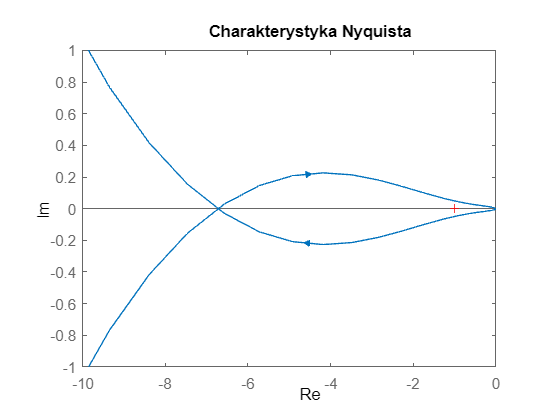

nyquist_comp(2, 1, 0.5, 0.01)

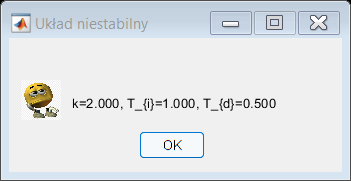

hurwitz_comp(2, 1, 0.5, 0.01)

### Stabilizacja układu ze względu na parametr k

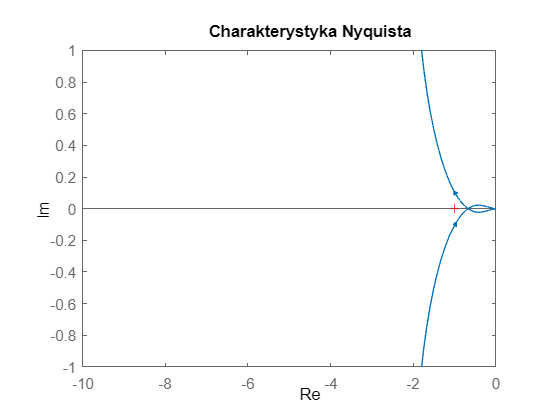

nyquist_comp(0.2, 1, 0.5, 0.01)

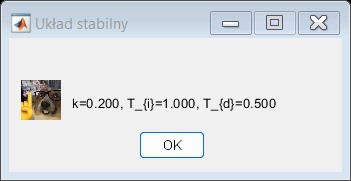

hurwitz_comp(0.2, 1, 0.5, 0.01)

### Stabilizacja ze względu na parametr Ti

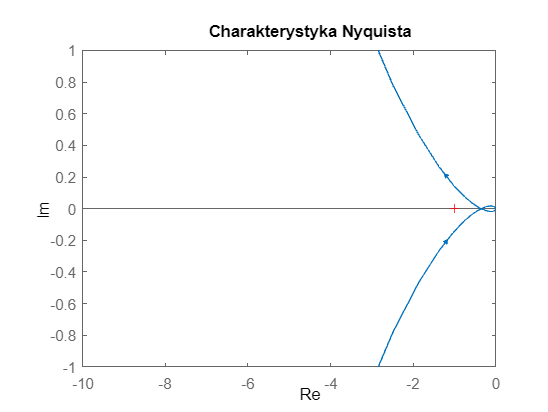

nyquist_comp(2, 1, 3, 0.01)

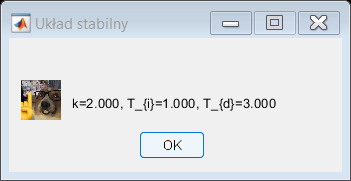

hurwitz_comp(2, 1, 3, 0.01)

### Stabilizacja ze względu na parametr Td

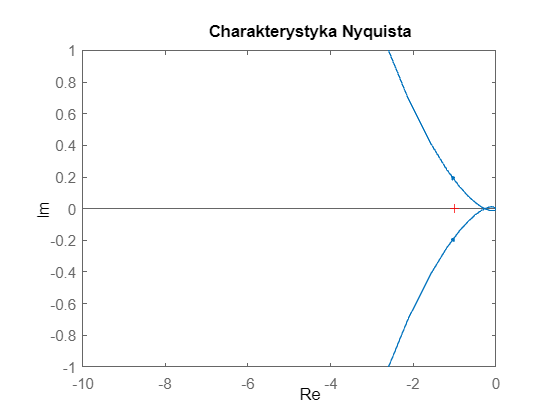

nyquist_comp(2, 1, 2, 0.01)

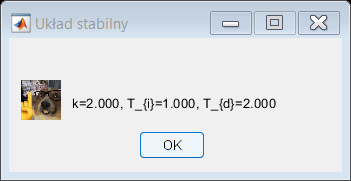

hurwitz_comp(2, 1, 2, 0.01)

### Inne nastawy regulatora

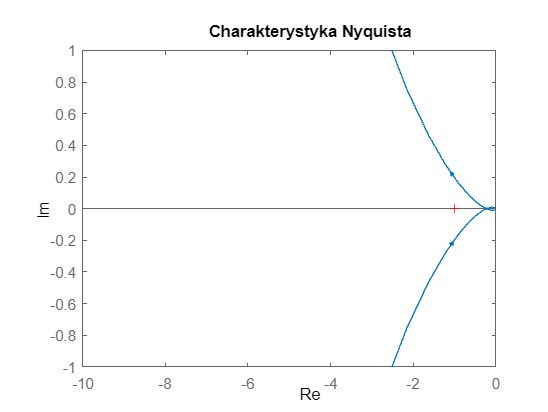

nyquist_comp(2, 1, 1.5, 0.01)

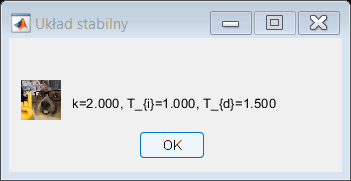

hurwitz_comp(2, 1, 1.5, 0.01)

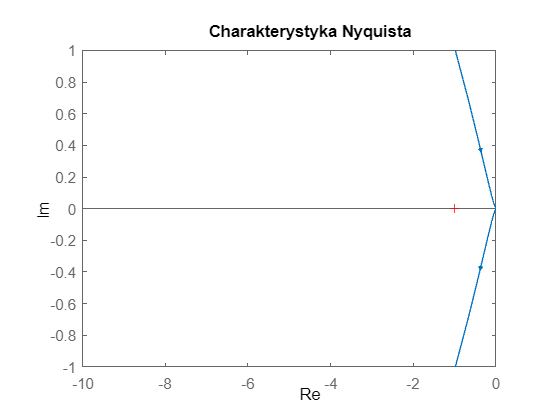

nyquist_comp(7, 2, 0.1, 0.01)

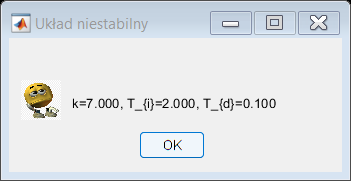

hurwitz_comp(7, 2, 0.1, 0.01)

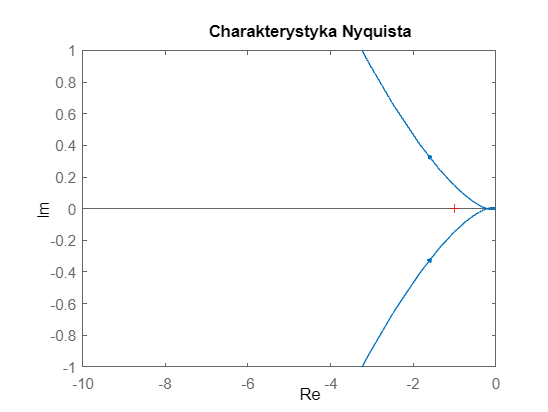

nyquist_comp(2, 1.1, 0.8, 0.01)

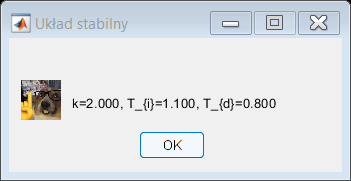

hurwitz_comp(2, 1.1, 0.8, 0.01)

### Odpowiedzi skokowe układu stabilnego i niestabilnego

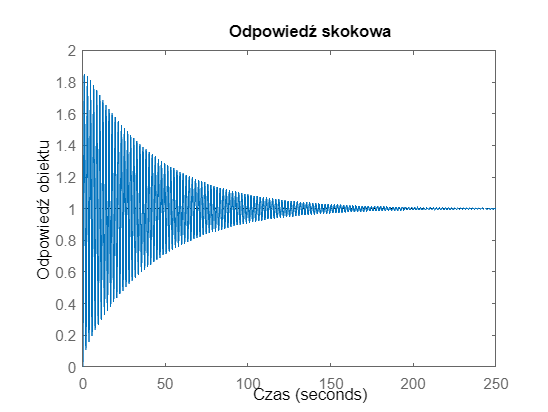

print_step(2, 3, 0.5, 0.01)

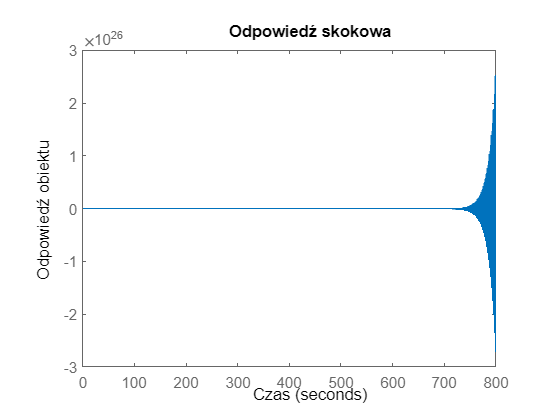

print_step(2, 1, 0.5, 0.01)

## Wnioski

Podczas laboratorium zbadana została stabilność zamkniętego układu z regulatorem PID. Do tego celu użyto kryterium Nyquista i kryterium Hurwitza. Wyznaczone zostały także odpowiedzi skokowe obiektu stabilnego i niestabilnego, na których widać odpowiednio gasnące i narastające oscylacje. 